# Creating an unfitted mesh function

## Introduction

In these tutorial files, you will learn how to use the various modules of Swan in order to generate your own FEM and Topology Optimization simulations. In each tutorial, a single building block will be analyzed, with some examples to make it easier. If you have any questions, feel free to create a new issue in the GitHub repository.

In this tutorial, we will learn how to obtain functions on different meshes from the unfitted mesh, given a function defined on a background mesh.

## Example with triangles

Let's start by using a background mesh of triangles. First, we need to create such mesh sample:

clear;

x1       = linspace(0,1,2);
x2       = linspace(0,1,2);
[xv,yv]  = meshgrid(x1,x2);
[F,V]    = mesh2tri(xv,yv,zeros(size(xv)),'x');
m.coord  = V(:,1:2);
m.connec = F;
mesh     = Mesh.create(m);

Then, we will create an unfitted mesh, using as initial level set a circle inclusion, which is obtained as follows

gPar.type         = 'Circle';
gPar.radius       = 0.25;
gPar.xCoorCenter  = 0.5;
gPar.yCoorCenter  = 0.5;
g                 = GeometricalFunction(gPar);
phiFun            = g.computeLevelSetFunction(mesh);
lsCircle          = phiFun.fValues;
lsCircleInclusion = -lsCircle;

and then introduced in the unfitted mesh:

sUm.backgroundMesh = mesh;
sUm.boundaryMesh   = mesh.createBoundaryMesh;
uMesh              = UnfittedMesh(sUm);
uMesh.compute(lsCircleInclusion);

Besides, we need a function defined on our background mesh. Consider the following analytical function:

sAF.fHandle = @(x) 1-(x(1,:,:)-0.5).^2-(x(2,:,:)-0.5).^2;
sAF.ndimf   = 1;
sAF.mesh    = mesh;
aFun        = AnalyticalFunction(sAF);

which plot can be obtained as

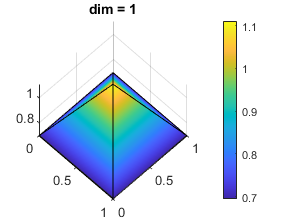

aFun.plot();
view(45,60);

Finally, we just need to run the following lines to obtain the same function evaluated on previous unfitted mesh.

uMeshFun = uMesh.obtainFunctionAtUnfittedMesh(aFun);
uMeshFun.plot();
view(45,60);

## Example with lines

Let's continue with a one dimensional mesh case. We will look for an unfitted mesh along a line. For the sake of simplicity, let's just build another triangular mesh in order to obtain the unfitted mesh, and later let's select one of the unfitted boundary meshes.

clear;

x1       = linspace(0,1,5);
x2       = linspace(0,1,5);
[xv,yv]  = meshgrid(x1,x2);
[F,V]    = mesh2tri(xv,yv,zeros(size(xv)),'x');
m.coord  = V(:,1:2);
m.connec = F;
mesh     = Mesh.create(m);

Let's use a vertical fiber inclusion now as initial case:

gPar.type          = 'VerticalFiber';
gPar.width         = 0.25;
gPar.xCoorCenter   = 0.5;
g                  = GeometricalFunction(gPar);
phiFun             = g.computeLevelSetFunction(mesh);
ls                 = phiFun.fValues;
lsInclusion        = -ls;
sUm.backgroundMesh = mesh;
sUm.boundaryMesh   = mesh.createBoundaryMesh;
uMesh              = UnfittedMesh(sUm);
uMesh.compute(lsInclusion);

Consider now, for instance, the third unfitted boundary mesh:

uMeshLine          = uMesh.unfittedBoundaryMesh.meshes{3};

Thus,

sAF.fHandle = @(x) 1-(x(1,:,:)-0.5).^2;
sAF.ndimf   = 1;
sAF.mesh    = uMeshLine.backgroundMesh;
aFun        = AnalyticalFunction(sAF);
uMeshFun    = uMeshLine.obtainFunctionAtUnfittedMesh(aFun);

## Example with quads

Let's continue with a mesh of quadrilaterals. The only difference is the way we can obtain the background mesh. In these cases, we can compute a quadrilateral mesh with the following class:

clear;

mesh = UnitQuadMesh(5,5);

Thus,

gPar.type          = 'Circle';
gPar.radius        = 0.25;
gPar.xCoorCenter   = 0.5;
gPar.yCoorCenter   = 0.5;
g                  = GeometricalFunction(gPar);
phiFun             = g.computeLevelSetFunction(mesh);
lsCircle           = phiFun.fValues;
lsCircleInclusion  = -lsCircle;
sUm.backgroundMesh = mesh;
sUm.boundaryMesh   = mesh.createBoundaryMesh;
uMesh              = UnfittedMesh(sUm);
uMesh.compute(lsCircleInclusion);


sAF.fHandle = @(x) 1-(x(1,:,:)-0.5).^2-(x(2,:,:)-0.5).^2;
sAF.ndimf   = 1;
sAF.mesh    = mesh;
aFun        = AnalyticalFunction(sAF);
aFun.plot();
view(45,45);

uMeshFun = uMesh.obtainFunctionAtUnfittedMesh(aFun);
uMeshFun.plot();
view(45,45);

## Example with tetrahedra

Let's continue with a mesh of tetrahedras. Again, the only difference is the way we can obtain the background mesh. We will compute it manually with the following lines:

clear;

X    = [0 ,0, 0;...
        1, 0, 0;...
        0, 1, 0;...
        1, 1, 0;...
        0, 0, 1;...
        1, 0, 1;...
        0, 1, 1;...
        1, 1, 1;];
s.coord  = X;
s.connec = delaunay(X);
mesh     = Mesh.create(s);

Thus,

gPar.type          = 'VerticalFiber';
gPar.width         = 0.5;
gPar.xCoorCenter   = 0.25;
g                  = GeometricalFunction(gPar);
phiFun             = g.computeLevelSetFunction(mesh);
ls                 = phiFun.fValues;
sUm.backgroundMesh = mesh;
sUm.boundaryMesh   = mesh.createBoundaryMesh;
uMesh              = UnfittedMesh(sUm);
uMesh.compute(ls);

sAF.fHandle = @(x) 1-(x(1,:,:)-0.5).^2-(x(2,:,:)-0.5).^2-(x(3,:,:)-0.5).^2;
sAF.ndimf   = 1;
sAF.mesh    = mesh;
aFun       = AnalyticalFunction(sAF);

uMeshFun = uMesh.obtainFunctionAtUnfittedMesh(aFun);
plot(uMeshFun)

## Example with hexahedra

Let's finish with a mesh of hexahedras. We will use a mesh previously prepared with GiD:

clear;

file       = 'toyExampleHexa';
a.fileName = file;
s          = FemDataContainer(a);
mesh       = s.mesh;
s          = [];

Thus,

gPar.type          = 'Cylinder';
gPar.radius        = 0.45;
gPar.xCoorCenter   = 0.5;
gPar.yCoorCenter   = 0.5;
g                  = GeometricalFunction(gPar);
phiFun             = g.computeLevelSetFunction(mesh);
ls                 = phiFun.fValues;

sUm.backgroundMesh = mesh;
sUm.boundaryMesh   = mesh.createBoundaryMesh;
uMesh              = UnfittedMesh(sUm);
uMesh.compute(ls);

sAF.mesh    = mesh;
sAF.fValues = [0;1;2;3;0;0;1;1;2;2;3;3;0;1;2;3];
sAF.order   = 'P1';
aFun        = LagrangianFunction(sAF);

uMeshFun = uMesh.obtainFunctionAtUnfittedMesh(aFun);

## Miss anything?

Feel free to create a new Issue in Swan's GitHub repository with any questions or doubts you may have. We will get back to you as soon as possible!